
%s=50
%t = 0:0.01:2*pi;
%for c = 1:s
%    f = c* exp(1i*t);
%    plot(real(f), imag(f));
%    hold on;    
%end
%hold off      
c = 1;
a = 0;
f = 0;
m = 1;
numberOfPDE = 1;
model = createpde(numberOfPDE);
geometryFromEdges(model,@squareg);


specifyCoefficients(model,"m",m,"d",0,"c",c,"a",a,"f",f);
applyBoundaryCondition(model,"dirichlet","Edge",[2,4],"u",0);
applyBoundaryCondition(model,"neumann","Edge",([1 3]),"g",0);
generateMesh(model);



u0 = @(location) atan(cos(pi/2*location.x));
ut0 = @(location) 3*sin(pi*location.x).*exp(sin(pi/2*location.y));
setInitialConditions(model,u0,ut0);


n = 60;
tlist = linspace(0,5,n);
model.SolverOptions.ReportStatistics ='on';
result = solvepde(model,tlist);

457 successful steps
38 failed attempts
992 function evaluations
1 partial derivatives
112 LU decompositions
991 solutions of linear systems


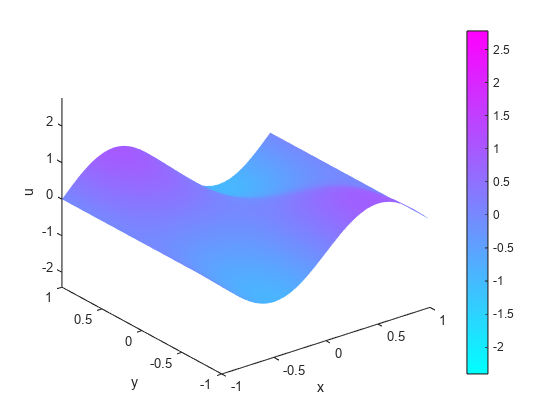

u = result.NodalSolution;
figure
umax = max(max(u));
umin = min(min(u));
for i = 1:n
    pdeplot(model,"XYData",u(:,i),"ZData",u(:,i), ...
                  "ZStyle","continuous","Mesh","off");
    axis([-1 1 -1 1 umin umax]); 
    clim([umin umax]);
    xlabel x
    ylabel y
    zlabel u
    M(i) = getframe;
end